addpath('/Users/markwoods/Documents/MATLAB/Practical4/Prac4/')
addpath('/Users/markwoods/Documents/MATLAB/Practical5/')
addpath '/Users/markwoods/Documents/MATLAB/Practical4/Prac4/SVM-KM'

[image_stream, labels] = loadPedestrianDatabase('People-Code/pedestrian_train.cdataset');

% display HOG for image1
if false
    test_image = imread('pos/img00000.jpg');
    hog = hog_feature_vector(test_image);
    subplot(1,2,1); imshow(test_image); subplot(1,2,2); showHog(hog, [size(test_image,1) size(test_image, 2)]);
end

% calculating HOG for all images
hogs = [];
square_images = [];
for im_index = 1:size(image_stream, 1)
    % converting image vector back to image
    image = reshape(image_stream(1, :), [160 96]);
    square_images(im_index, :, :) = image;
    % calculating hogs
    new_hog = hog_feature_vector(image);
    hogs = [hogs; new_hog];
end
% displaying image and HOG for first of all images
image = square_images(1, :, :);
image = uint8(reshape(image, [160 96]));
subplot(1,2,1); imshow(image); subplot(1,2,2); showHog(hogs(1,:), [size(image,1) size(image, 2)]);

% training SVM system using this data
modelSVM = SVMtraining(hogs, labels);

building the distance matrix
in QP
      Cost     Delta Cost  #support  #up saturate
|  0.0000e+00 |   1.0000 |      1 |      0 |
|  0.0000e+00 |   0.0000 |      2 |      0 |


out QP
max(alpha)
   NaN


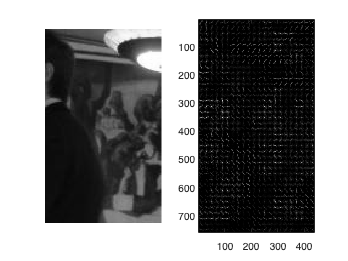


% testing SVM system 
% importing data
[test_image_stream, test_labels] = loadPedestrianDatabase('People-Code/pedestrian_test.cdataset');

% calculating HOG for all test images
test_hogs = [];
test_square_images = [];
for im_index = 1:size(test_image_stream, 1)
    % converting image vector back to image
    image = reshape(test_image_stream(1, :), [160 96]);
    test_square_images(im_index, :, :) = image;
    % calculating hogs
    new_hog = hog_feature_vector(image);
    test_hogs = [test_hogs; new_hog];
end
% displaying image and HOG for first of all images
image = test_square_images(1, :, :);
image = uint8(reshape(image, [160 96]));
subplot(1,2,1); imshow(image); subplot(1,2,2); showHog(test_hogs(1,:), [size(image,1) size(image, 2)]);


counter=0

counter = 0

for im_index=1:size(test_image_stream,1)
    testnumber= test_hogs(im_index,:);
    classificationResult(im_index,1) = SVMTesting(testnumber,modelSVM);
end


## Evaluation

comparison = (test_labels==classificationResult);
Accuracy = sum(comparison)/length(comparison)

Accuracy = 0.3313